# Parameter Pruning and Quantization of Image Classification Network

This assignment shows how to prune the parameters of a trained neural network by using structured pruning.

In many applications where you use transfer learning to retrain an image classification network for a new task or where you train a new network from scratch, you do not know the optimal network architecture, and the network can be overparameterized. An overparameterized network has redundant connections. Pruning identifies redundant connections that you can remove without affecting the network accuracy.

This example shows how to:

- Train a simple digit classification convolutional neural network

- Perform post-training, iterative, structured pruning without the need for training data

- Evaluate the impact of different pruning ratios on classification accuracy

- Evaluate the impact of quantization on the classification accuracy of the pruned network

This example uses a simple convolutional neural network to classify user-written digits from 0 to 9. For more information on setting up the data used for training and validation, see [Create Simple Deep Learning Network for Classification](docid:nnet_ug#example-ex86195632). 

Structured pruning eliminates connections by removing entire filters/channels from the network. Structured pruning in combination with quantization can improve the inference speed and reduce the memory footprint of a network. For an example of structured pruning, see [Prune Image Classification Network Using Taylor Scores](docid:nnet_ug#mw_50dcca82-6e22-482d-85d3-daae131e2fa4).

## Utility Functions

### Load Digits Data set Function

The `loadDigitDataset `function loads the Digits data set and splits the data into training and validation data.

function [imdsTrain, imdsValidation] = loadDigitDataset()
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
[imdsTrain, imdsValidation] = splitEachLabel(imds,0.75,"randomized");
end

### Train Digit Recognition Network Function

The `trainDigitDataNetwork` function trains a convolutional neural network to classify digits in grayscale images.

function net = trainDigitDataNetwork(imdsTrain,imdsValidation)
layers = [
    imageInputLayer([28 28 1],"Normalization","rescale-zero-one")
    % ConvBlock 1 (no need to change this)
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    
    % ConvBlock 2 (no need to change this)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    % ConvBlock 3 (no need to change this)
    convolution2dLayer(3,32,'Padding','same')
    reluLayer
    
    % OutputBlock (no need to change this)
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

% Specify the training options
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','none',"ExecutionEnvironment","auto");

% Train network
net = trainNetwork(imdsTrain,layers,options);

% saves the 'net' model as 'digitsNet.mat'
save('digitsNet.mat','net')
end

### Mini Batch Preprocessing Function

The `preprocessMiniBatch` function preprocesses a mini-batch of predictors by extracting the image data from the input cell array and concatenate into a numeric array. For grayscale input, concatenating the data over the fourth dimension adds a third dimension to each image to use as a singleton channel dimension.

function X = preprocessMiniBatch(XCell)
% Extract image data from cell and concatenate.
X = cat(4,XCell{:});
end

### Model Accuracy Function

Evaluate the classification accuracy of the `dlnetwork`. Accuracy is the percentage of labels correctly classified by the network.

function accuracy = evaluateAccuracy(dlnet,mbqValidation,classes,trueLabels)
YPred = modelPredictions(dlnet,mbqValidation,classes);
accuracy = mean(YPred == trueLabels);
end

### Model Predictions Function

The `modelPredictions` function takes as input a `dlnetwor`k object dlnet, a `minibatchqueue` of input data `mbq`, and the network classes, and computes the model predictions by iterating over all data in the minibatchqueue object. The function uses the `onehotdecode` function to find the predicted class with the highest score.

function predictions = modelPredictions(dlnet,mbq,classes)
predictions = [];
while hasdata(mbq)
    dlXTest = next(mbq);
    dlYPred = softmax(predict(dlnet,dlXTest));
    YPred = onehotdecode(dlYPred,classes,1)';
    predictions = [predictions; YPred];
end
reset(mbq)
end

### Find Convolution, BatchNorm, FC Layers

function indices = findConvLayers(layers)
    indices = find(arrayfun(@(l) isa(l, 'nnet.cnn.layer.Convolution2DLayer'), layers));
end

function indices = findBatchNormLayers(layers)
    indices = find(arrayfun(@(l) isa(l, 'nnet.cnn.layer.BatchNormalizationLayer'), layers));
end

function indices = findFCLayers(layers)
    indices = find(arrayfun(@(l) isa(l, 'nnet.cnn.layer.FullyConnectedLayer'), layers));
end

### Extract Weights and Filters

function [weights, numFilters] = getConvWeights(net, convIndices)
    weights = cell(length(convIndices),1);
    numFilters = zeros(length(convIndices),1);
    for i = 1:length(convIndices)
        layer = net.Layers(convIndices(i));
        weights{i} = layer.Weights;
        numFilters(i) = size(layer.Weights,4); % Number of output channels
    end
end

### Compute L1 Score for Pruning

function pruneFilters = computeL1Pruning(weights, prune_ratio)
    % COMPUTE L1 PRUNING: Prunes filters based on L1 norm
    norms = cellfun(@(w) sum(abs(w), [1,2,3]), weights, 'UniformOutput', false);
    thresholds = cellfun(@(n) quantile(n, prune_ratio), norms, 'UniformOutput', false);
    pruneFilters = cellfun(@(n, t) n <= t, norms, thresholds, 'UniformOutput', false);

    % Ensure at least one filter remains per layer
    for i = 1:numel(pruneFilters)
        if all(pruneFilters{i}) % If all filters are pruned
            [~, minIdx] = min(norms{i}); % Find the filter with the smallest L1 norm
            pruneFilters{i}(minIdx) = false; % Retain this filter
        end
    end
end

### Prune Network

function net = pruneNetwork(net, convIndices, bnIndices, fcIndex, pruneFilters)
    layers = net.Layers;
    
    for i = 1:length(convIndices)
        idx = convIndices(i);
        layer = layers(idx);
        keepIdx = find(~pruneFilters{i}); % Indices of filters to keep
        
        % Step 1: Create a new convolution layer with pruned filters
        newLayer = convolution2dLayer(layer.FilterSize, numel(keepIdx), ...
            'Padding', layer.PaddingSize, ...
            'Stride', layer.Stride, ...
            'WeightsInitializer', 'glorot', ...
            'BiasInitializer', 'zeros');
        
        % Copy trained weights and biases (ensure correct dimensions)
        newLayer.Weights = layer.Weights(:,:,:,keepIdx);  % Assign pruned weights
        newLayer.Bias = layer.Bias(keepIdx);  % Assign pruned biases
        
        % Retain original layer name
        newLayer.Name = layer.Name;

        % Replace pruned layer in network
        layers(idx) = newLayer;

        bnIdx = bnIndices(bnIndices > idx);  % Get indices of BatchNorm layers after the conv layer
        if ~isempty(bnIdx)
            % Assume the first BatchNorm layer after the conv layer is the one we need
            bnIdx = bnIdx(1);
            
            % Create a new BatchNorm layer to match the pruned filters
            newBNLayer = batchNormalizationLayer;
            
            % Copy and update the BatchNorm parameters to reflect the pruned filters
            newBNLayer.Offset = layers(bnIdx).Offset(keepIdx);
            newBNLayer.Scale = layers(bnIdx).Scale(keepIdx);
            newBNLayer.TrainedMean = layers(bnIdx).TrainedMean(keepIdx);
            newBNLayer.TrainedVariance = layers(bnIdx).TrainedVariance(keepIdx);
            
            % Retain original layer name
            newBNLayer.Name = layers(bnIdx).Name;

            % Replace old BatchNorm layer with the new one
            layers(bnIdx) = newBNLayer;
        end
        
        % TODO: Adjust the input channels of the next conv layer due to the previous conv layer's pruning
        if i < length(convIndices) % Ensure it's not the last Conv layer
            %TODO: Get the next conv layer
            nextConvIdx = convIndices(i+1);
            nextLayer = layers(nextConvIdx);

            % Step 1: Create a new convolution layer with pruned filters
            % HINT: you need to also adjust the parameter 'NumChannels' for the expected input channels
            newnextLayer = convolution2dLayer(nextLayer.FilterSize, nextLayer.NumFilters, ...
        'Padding', nextLayer.PaddingSize, 'Stride', nextLayer.Stride, 'NumChannels', numel(keepIdx));
            
            %TODO: Copy trained weights and biases (ensure correct dimensions)
            % HINT: remember you are modifying the input channels, not output for the next layer!!
            newnextLayer.Weights = nextLayer.Weights(:, :, keepIdx, :);
            newnextLayer.Bias = nextLayer.Bias;

            % Retain original layer name
            newnextLayer.Name = nextLayer.Name;

            % Replace next conv layer in network with new adjusted layer
            layers(nextConvIdx) = newnextLayer;
        end        
    end

    % redefine the FC-layer
    % since pruning reduces the number of channels, the input shape to the
    % FC-layer also needs to be changed and redefined

    % Compute the number of inputs to the FC layer
    numInputs  = computeFCInputSize(layers, convIndices);    
    numOutputs = 10; % Number of classes
    
    % Compute the Glorot-initialized weight matrix
    weights_fc = initializeGlorot(numOutputs, numInputs);

    fc_name = layers(fcIndex).Name; % Preserve name
    fc_bias = layers(fcIndex).Bias; % Preserve Bias
    layers(fcIndex) = fullyConnectedLayer(numOutputs);
    layers(fcIndex).Weights = weights_fc;
    layers(fcIndex).Bias = fc_bias;
    
    % Retain original layer name
    layers(fcIndex).Name = fc_name;

    % Reassemble the network with pruned layers
    net = assembleNetwork(layers);
end

### Weight Initializations

function weights = initializeGlorot(numOutputs, numInputs)
    % Initialize weights using Glorot (Xavier) uniform distribution
    Z = 2*rand(numOutputs, numInputs,'single') - 1;  % Uniform distribution [-1, 1]
    bound = sqrt(6 / (numInputs + numOutputs));  % Glorot bound
    weights = bound * Z;  % Scale weights within the Glorot range
end

### Compute Final Output Shape

function numInputs = computeFCInputSize(layers, convIndices)
    % COMPUTEFCINPUTSIZE Computes the number of inputs to the FC layer
    % after the last convolutional layer in a given network.
    %
    % INPUTS:
    %   - layers: Array of layers from a deep learning network.
    %   - convIndices: Indices of convolutional layers in the network.
    %
    % OUTPUT:
    %   - numInputs: Total number of input parameters to the FC layer.
    
    % Step 1: Create a dummy input tensor
    inputSize = layers(1).InputSize;  % Get input size of the network
    dummyInput = dlarray(zeros(inputSize, 'single'), 'SSCB');  % (Spatial-Spatial-Channel-Batch)
    
    % Step 2: Convert to dlnetwork for layer-wise inference
    lgraph = layerGraph(layers);
    lgraph = removeLayers(lgraph,["softmax","classoutput","fc"]);
    dlnet = dlnetwork(lgraph);    

    % Step 3: Extract the last convolutional layer output
    lastConvIdx = convIndices(end);  % Index of the last Conv layer
    features = forward(dlnet, dummyInput, 'Outputs', layers(lastConvIdx).Name);
    
    % Step 4: Compute the output size
    [H_final, W_final, C_final, ~] = size(features);  % Spatial and channel dimensions
    
    % Step 5: Compute total number of inputs for the FC layer
    numInputs = H_final * W_final * C_final;
end

## Part 1. Train the digits Network

Load the training and validation data. Train a convolutional neural network for the classification task. 

[imdsTrain, imdsValidation] = loadDigitDataset;
net = trainDigitDataNetwork(imdsTrain, imdsValidation);
trueLabels = imdsValidation.Labels;
classes = categories(trueLabels);

Create a `minibatchqueue` object containing the validation data. Set `executionEnvironment` to auto to evaluate the network on a GPU, if one is available. By default, the `minibatchqueue` object converts each output to a `gpuArray` if a GPU is available. Using a GPU requires Parallel Computing Toolbox™ and a supported GPU device. For information on supported devices, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f).

executionEnvironment = "auto";
miniBatchSize = 128;
imdsValidation.ReadSize = miniBatchSize;
mbqValidation = minibatchqueue(imdsValidation,1,...
    'MiniBatchSize',miniBatchSize,...
    'MiniBatchFormat','SSCB',...
    'MiniBatchFcn',@preprocessMiniBatch,...
    'OutputEnvironment',executionEnvironment);

### **Convert to **[**dlnetwork**](docid:nnet_ref#object_dlnetwork) `Object`

Convert the network to a layer graph and remove the layers used for classification using `removeLayers`. This allows us to create a custom cost function and evaluate the gradients with respect to the cost function to calculate the parameter score.

lgraph = layerGraph(net.Layers);
lgraph = removeLayers(lgraph,["softmax","classoutput"]);
dlnetog = dlnetwork(lgraph);

Use `analyzeNetwork` to analyze the network architecture and learnable parameters. 

% analyzeNetwork(dlnetog) % you can comment this out after you run it once (it's for visualization purposes)

Evaluate the accuracy of the network.

accuracyOriginalNet = evaluateAccuracy(dlnetog,mbqValidation,classes,trueLabels)

accuracyOriginalNet = 0.9948

## Part 2. Neural Network Pruning

The goal of neural network pruning is to identify and remove unimportant connections to reduce the size of the network without affecting network accuracy. In the following figure, on the left, the network has connections that map each neuron to the neuron of the next layer. After pruning, the network has fewer connections than the original network.

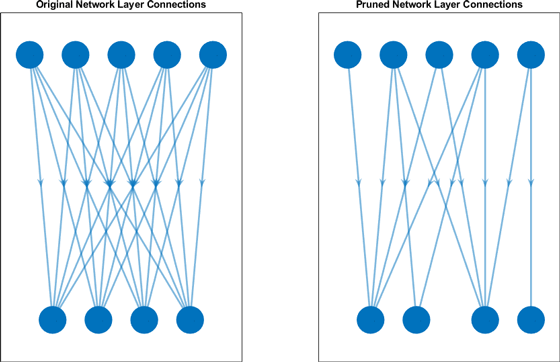

A pruning algorithm assigns a score to each parameter in the network. The score ranks the importance of each connection in the network. You can use one of two pruning approaches to achieve a target sparsity:

- One-shot pruning - Remove a specified percentage of connections based on their score in one step. This method is prone to layer collapse when you specify a high sparsity value.

- Iterative pruning - Achieve the target sparsity in a series of iterative steps. You can use this method when evaluated scores are sensitive to network structure. Scores are reevaluated at every iteration, so using a series of steps allows the network to move toward sparsity incrementally.

This example uses the iterative pruning method to achieve a target sparsity.

## 2.2 Iterative Pruning  

                                                                                          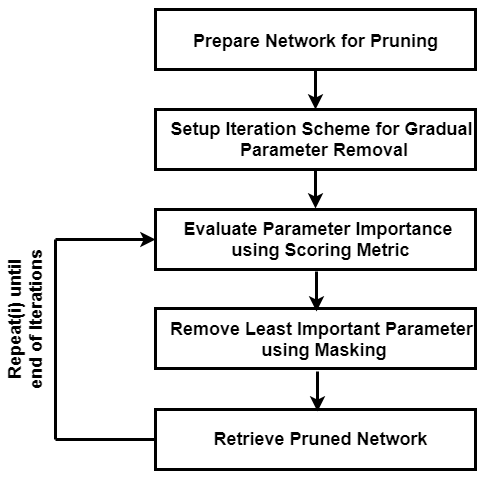

The layers with learnable parameters are computed below.

numTotalParamsOG = sum(cellfun(@numel,dlnetog.Learnables.Value))
numNonZeroPerParamOG = cellfun(@(w)nnz(extractdata(w)),dlnetog.Learnables.Value)

numTotalParamsOG = 21626

numNonZeroPerParamOG =           72
           8
           8
           8
        1152
          16
          16
          16
        4608
          32


**Channel/Filter Pruning Loop**

For each iteration, the custom pruning loop in this example performs the following steps:

- Calculate the score (in this case the L1 norm) for each channel.

- Rank the scores for all channels in the network based on the selected pruning algorithm.

- Determine the threshold for removing connections with the lowest scores.

- Prune the channels/filters and reinitialize a new layers without the pruned weight

### Magnitude (L1 Norm) Pruning

% Load the trained model
load('digitsNet.mat','net');

% Find convolution layers
convIndices = findConvLayers(net.Layers);

% Find all BatchNorm layer indices
bnIndices = findBatchNormLayers(net.Layers);

% Find final FC layer index
fcIndex = findFCLayers(net.Layers);

% Set pruning hyperparameters
prune_ratio = 0.10;          % Prune 10% per iteration
prune_iterations = int32(1/prune_ratio) - 1;  % Stop before reaching 0 filters
prune_step = 0;              % Iteration counter

% TODO: declare variables for:
% prunedChannelsPerLayer (to track number of filters pruned per conv layer)
% numOutChannelsPerLayer (the original number of filters per conv layer)
[~, numOutChannelsPerLayer] = getConvWeights(net, convIndices);
prunedChannelsPerLayer = zeros(size(numOutChannelsPerLayer));

% Store pruned filter/channel indices per iteration (for later plotting)
prunedIndices = cell(prune_iterations, 1);

% Store accuracy results
prunedAccuracies = zeros(prune_iterations, 1);

% Load training and validation datasets
[imdsTrain, imdsValidation] = loadDigitDataset();

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','none', "ExecutionEnvironment", "auto");

iter = 1;
while true
    % Get all convolution layer weights and current filter counts
    [convWeights, numFilters] = getConvWeights(net, convIndices);
    
    % Compute L1 norm of each filter (pruning score metric)
    pruneFilters = computeL1Pruning(convWeights, prune_ratio);
    
    % Check if the maximum pruning iterations have been reached
    if iter - 1 >= prune_iterations
        break;
    end

    % TODO: Modify network by pruning identified filters
    net = pruneNetwork(net, convIndices, bnIndices, fcIndex, pruneFilters);

    % TODO: Convert to lgraph for training
    
    % TODO: Retrain the network after pruning
    net = trainNetwork(imdsTrain, net.Layers, options);
    
    % TODO: Evaluate pruned model
    % Convert the pruned network to a dlnetwork for evaluation (if needed)
    
    % TODO: Evaluate and store accuracy per iteration in prunedAccuracies
    YPred = classify(net, imdsValidation);
    acc = mean(YPred == imdsValidation.Labels);
    prunedAccuracies(iter) = acc;
    
    % Update prunedChannelsPerLayer for each conv layer:
    [~, currentNumFilters] = getConvWeights(net, convIndices);
    prunedChannelsPerLayer = numOutChannelsPerLayer - currentNumFilters;
    prunedIndices{iter} = prunedChannelsPerLayer;
    
    % For logging: compute total number of parameters in the dlnetwork
    numTotalParams = sum(cellfun(@numel, dlnet.Learnables.Value));
    pruned_model_name = sprintf('digitsNet_%.2f_iterativePruned_params_%d.mat', round(iter*prune_ratio,2), numTotalParams);
    
    % Save the pruned model for the current iteration
    save(pruned_model_name, 'net');
    
    iter = iter + 1;
end


Iterative Pruning Accuracies per Iteration:


% Display the pruned accuracies for each iteration

    0.9964
    0.9964
    0.9960
    0.9948
    0.9932
    0.9904
    0.9776
    0.9872
    0.9904



disp('Iterative Pruning Accuracies per Iteration:');
disp(prunedAccuracies);

### Plot the original accuracy and pruned accuracies vs prune ratio

% TODO: Display the pruning progress

numIterations = 9; 
targetSparsity = 0.90;
iterationScheme = linspace(0,targetSparsity,numIterations);
figure
plot(100*iterationScheme([1,end]),100*accuracyOriginalNet*[1 1],'*-b','LineWidth',2,"Color","b")
ylim([0 100])
xlim(100*iterationScheme([1,end]))
xlabel("Sparsity (%)")
ylabel("Accuracy (%)")
legend("Original Accuracy","Location","southwest")
title("Pruning Accuracy")    
grid on

lineAccuracyPruning = animatedline('Color','g','Marker','o','LineWidth',1.5);
legend("Original Accuracy","Pruning Accuracy","Location","southwest")
%TODO: need to loop through the values and draw
for idx = 1:length(iterationScheme)
    sparsity = 100 * iterationScheme(idx);         % Convert sparsity to percentage
    pruned_accuracy = 100 * prunedAccuracies(idx);     % Convert accuracy to percentage
    addpoints(lineAccuracyPruning, sparsity, pruned_accuracy);
    drawnow;
end

### Plot the pruned channel per layer vs number of output channels per layer

% TODO: Display the pruning statistics
% TODO: need to compute prunedChannelsPerLayer & numOutChannelsPerLayer for generating the bar-graph in the pruning loop
figure
bar([prunedChannelsPerLayer,numOutChannelsPerLayer-prunedChannelsPerLayer],"stacked")
xlabel("Layer")
ylabel("Number of filters")
title("Number of filters per layer")
xticks(1:(numel(layerNames)))
xticklabels(layerNames)
xtickangle(45)
legend("Pruned number of channels/neurons" , "Original number of channels/neurons","Location","southoutside")
set(gca,'TickLabelInterpreter','none')

### Evaluate Network Accuracy

Compare the accuracy of the network before and after pruning.

YPredOriginal = modelPredictions(dlnet,mbqValidation,classes);
accOriginal = mean(YPredOriginal == trueLabels)
YPredPruned = modelPredictions(prunedDLNet,mbqValidation,classes);
accPruned = mean(YPredPruned == trueLabels)

Create a confusion matrix chart to explore the true class labels to the predicted class labels for the original and pruned network.

figure
confusionchart(trueLabels,YPredOriginal);
title("Original Network")

The validation set of the digits data contains 250 images for each class, so if a network predicts the class of each image perfectly, all scores on the diagonal equal 250 and no values are outside of the diagonal.

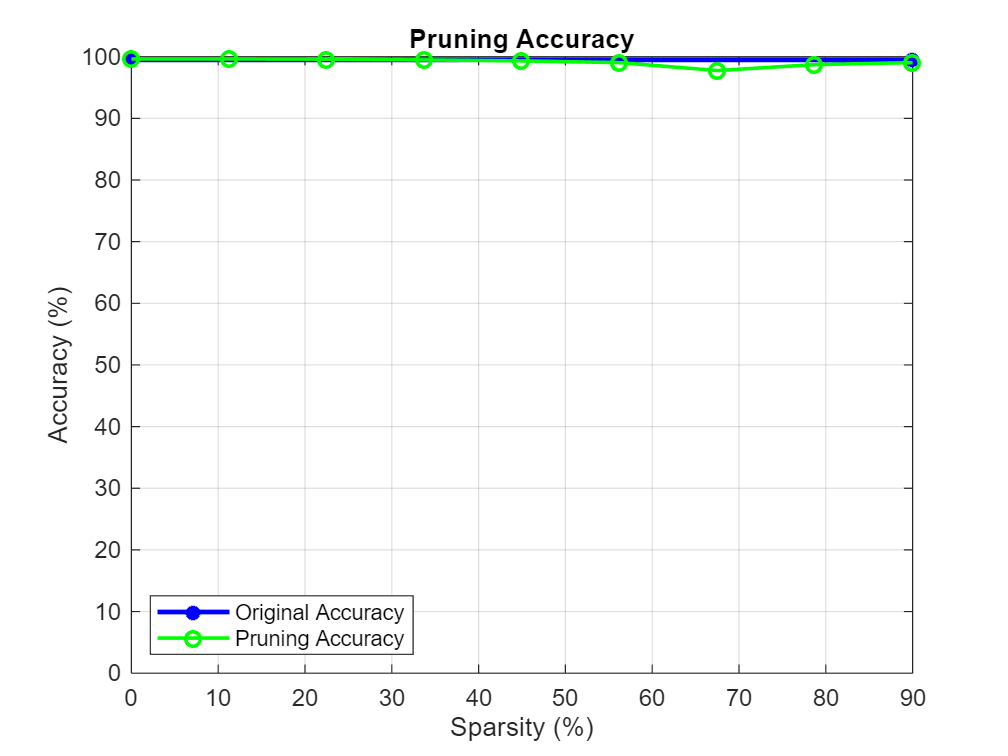

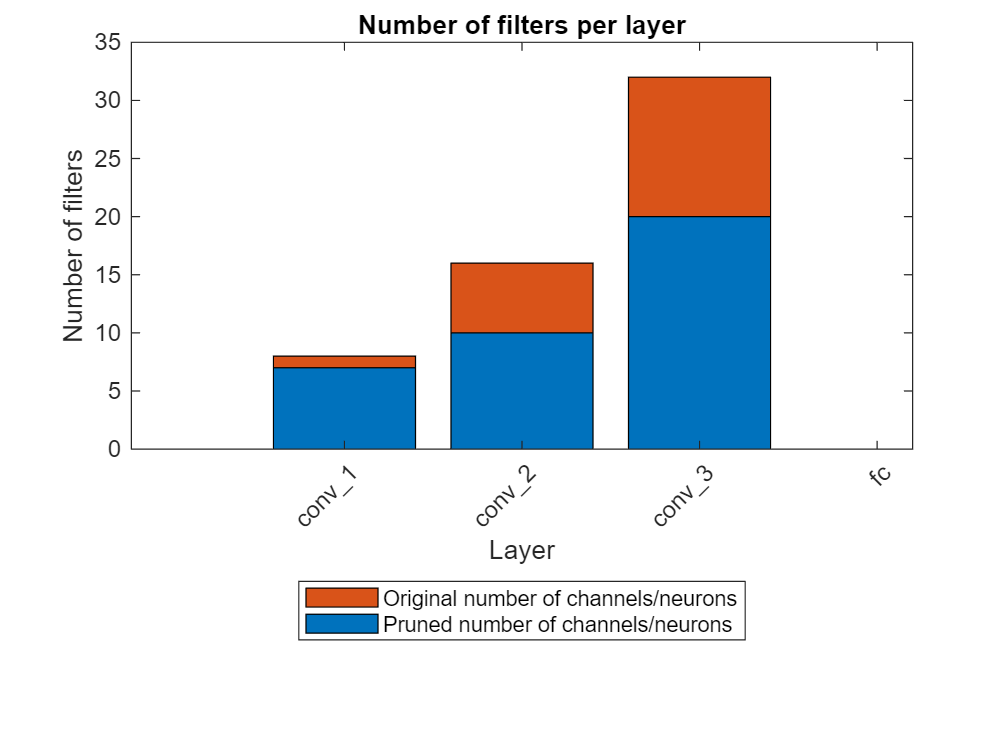

accOriginal = 0.9988

accPruned = 0.8920

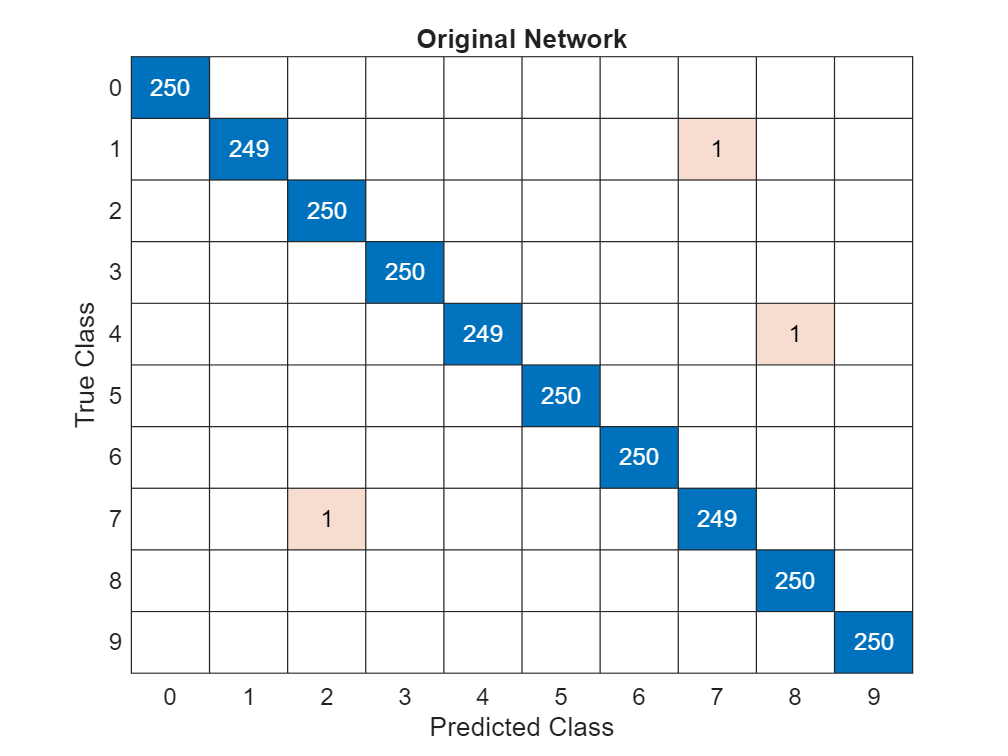

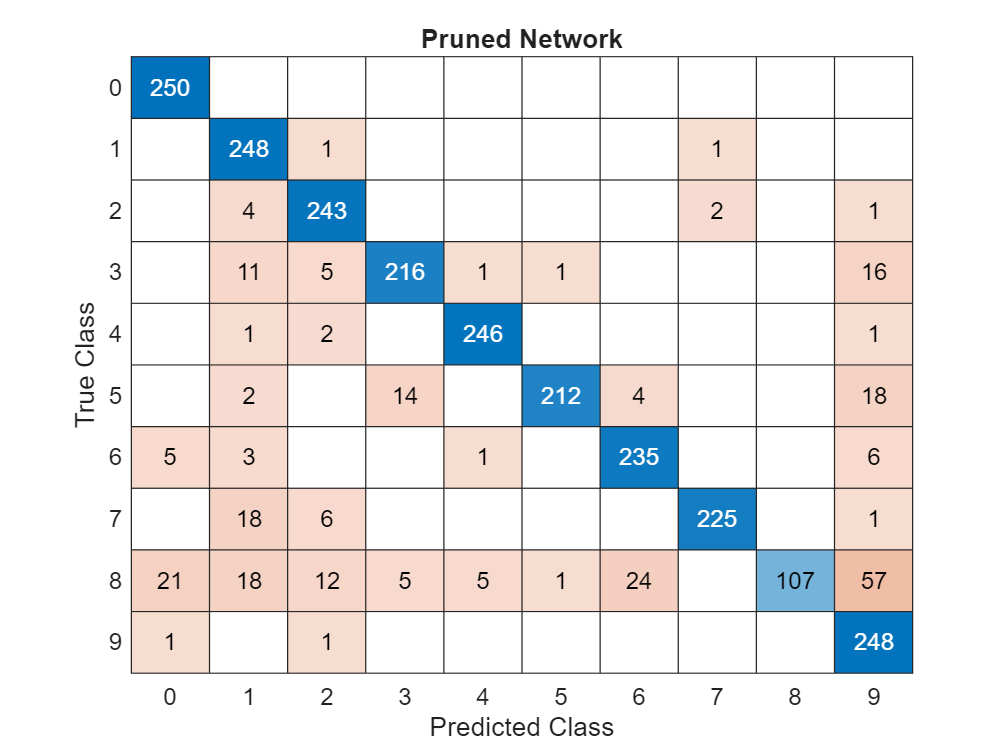

confusionchart(trueLabels,YPredPruned);

title("Pruned Network")

## 2.2 One-short Pruning

% Define a set of one-shot prune ratios (the desired fraction of filters to prune)
pruneRatios = 0.1:0.1:0.9;
numRatios = length(pruneRatios);
prunedAccuracies = zeros(numRatios, 1);
sparsityValues   = zeros(numRatios, 1);
% To store per-layer pruning details for later plotting
allPrunedChannels = cell(numRatios, 1);
allRemainingFilters = cell(numRatios, 1);

% Load baseline network and compute its accuracy
load('digitsNet.mat', 'net');

% Identify convolutional layers and get the original number of filters per layer
convIndices = findConvLayers(net.Layers);
[~, numOutChannelsPerLayer] = getConvWeights(net, convIndices);

% Loop over each one-shot prune ratio
for i = 1:numRatios
    currentRatio = pruneRatios(i);
    
    % Reload the baseline network (to avoid compounding pruning effects)
    load('digitsNet.mat', 'net');
    
    % Compute one-shot pruning mask for the current prune ratio
    [convWeights, ~] = getConvWeights(net, convIndices);
    pruneFilters = computeL1Pruning(convWeights, currentRatio);
    
    % Identify BatchNorm and FC layer indices
    bnIndices = findBatchNormLayers(net.Layers);
    fcIndex   = findFCLayers(net.Layers);
    
    % Apply one-shot pruning
    netPruned = pruneNetwork(net, convIndices, bnIndices, fcIndex, pruneFilters);
    
    % Retrain the pruned network
    options = trainingOptions('sgdm', ...
        'InitialLearnRate', 0.01, ...
        'MaxEpochs', 10, ...
        'Shuffle', 'every-epoch', ...
        'ValidationData', imdsValidation, ...
        'ValidationFrequency', 30, ...
        'Verbose', false, ...
        'Plots', 'none');
    
    lgraph = layerGraph(netPruned.Layers);
    netPruned = trainNetwork(imdsTrain, lgraph, options);
    
    % Evaluate pruned network accuracy
    YPred = classify(netPruned, imdsValidation);
    acc = mean(YPred == trueLabels);
    prunedAccuracies(i) = acc;
    
    % Compute the number of filters per layer after pruning and overall sparsity
    [~, currentNumFilters] = getConvWeights(netPruned, convIndices);
    prunedChannels = numOutChannelsPerLayer - currentNumFilters;
    totalOrig = sum(numOutChannelsPerLayer);
    totalPruned = sum(prunedChannels);
    sparsity = totalPruned / totalOrig;
    sparsityValues(i) = sparsity;
    
    allPrunedChannels{i} = prunedChannels;
    allRemainingFilters{i} = currentNumFilters;
    
    fprintf('One-shot Prune Ratio %.1f, Actual Sparsity: %.2f%%, Accuracy: %.2f%%\n', ...
        currentRatio, 100 * sparsity, 100 * acc);
    
    % (Optional) Save the pruned model for this prune ratio
    pruned_model_name = sprintf('digitsNet_%.2f_oneshotPruned.mat', currentRatio);
    save(pruned_model_name, 'netPruned');
end

One-shot Prune Ratio 0.1, Actual Sparsity: 10.71%, Accuracy: 99.40%
One-shot Prune Ratio 0.2, Actual Sparsity: 19.64%, Accuracy: 99.32%
One-shot Prune Ratio 0.3, Actual Sparsity: 30.36%, Accuracy: 99.56%
One-shot Prune Ratio 0.4, Actual Sparsity: 39.29%, Accuracy: 99.44%
One-shot Prune Ratio 0.5, Actual Sparsity: 50.00%, Accuracy: 99.04%
One-shot Prune Ratio 0.6, Actual Sparsity: 60.71%, Accuracy: 98.36%
One-shot Prune Ratio 0.7, Actual Sparsity: 69.64%, Accuracy: 96.12%
One-shot Prune Ratio 0.8, Actual Sparsity: 80.36%, Accuracy: 93.52%
One-shot Prune Ratio 0.9, Actual Sparsity: 89.29%, Accuracy: 79.04%


### Plot the original accuracy and pruned accuracies vs prune ratio

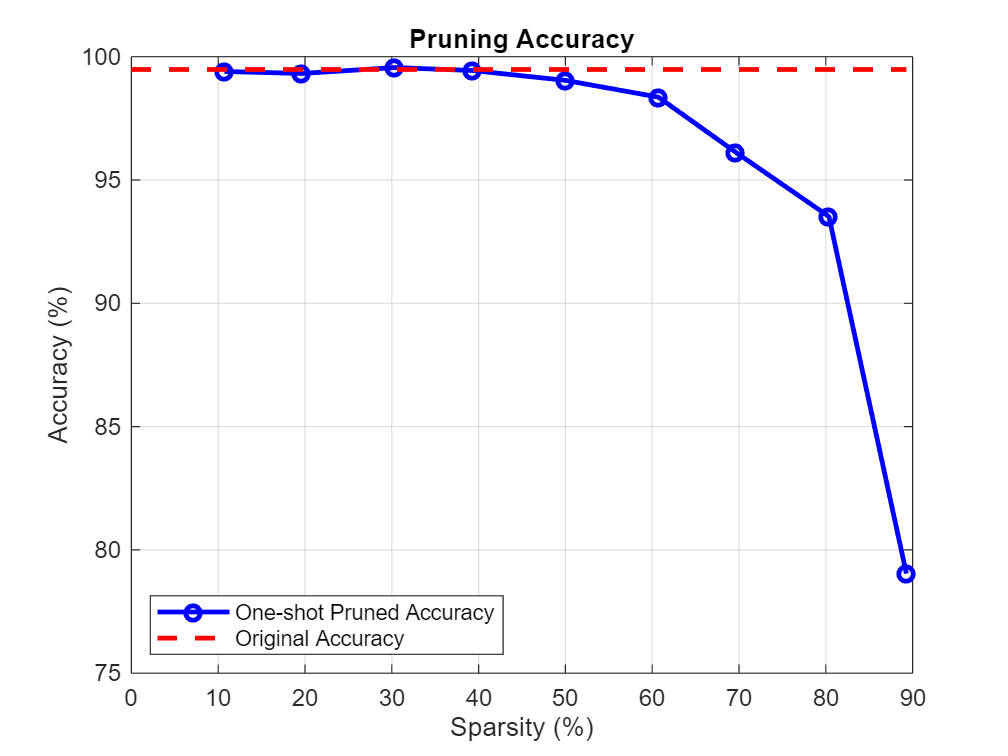

%% Plotting: Accuracy vs. Sparsity for One-shot Pruning
figure;
plot(100 * sparsityValues, 100 * prunedAccuracies, 'o-b', 'LineWidth', 2);
hold on;
plot([0, 100 * sparsityValues(end)], 100 * accuracyOriginalNet * [1, 1], '--r', 'LineWidth', 2);
xlabel('Sparsity (%)');
ylabel('Accuracy (%)');
legend('One-shot Pruned Accuracy', 'Original Accuracy', 'Location', 'southwest');
title('Pruning Accuracy');
grid on;
hold off;

### **Plot the pruned channel per layer vs number of output channels per layer**

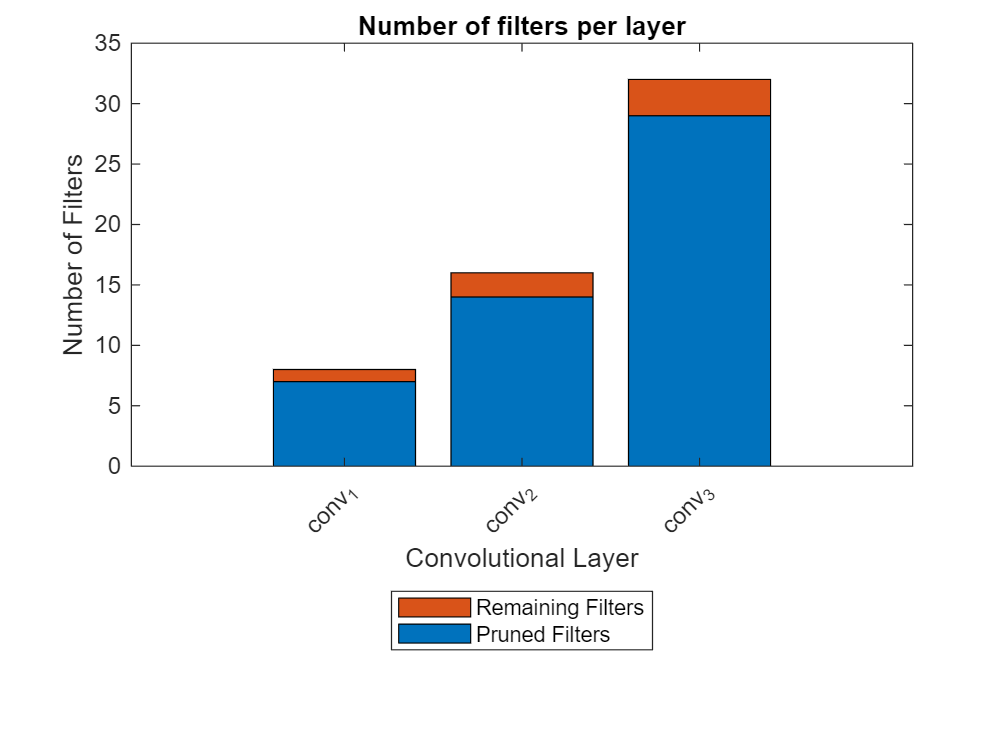

%% Plotting: Pruned Channels per Layer vs. Original Channels
% For illustration, use the last (highest) prune ratio's results
selectedIdx = numRatios;
selectedPrunedChannels = allPrunedChannels{selectedIdx};
selectedRemainingFilters = allRemainingFilters{selectedIdx};

numConvLayers = length(convIndices);
figure;
bar([selectedPrunedChannels, selectedRemainingFilters], 'stacked');
xlabel('Convolutional Layer');
ylabel('Number of Filters');
title('Number of filters per layer');
xticks(1:numConvLayers);
layerNames = arrayfun(@(idx) net.Layers(convIndices(idx)).Name, 1:numConvLayers, 'UniformOutput', false);
xticklabels(layerNames);
xtickangle(45);
legend('Pruned Filters', 'Remaining Filters', 'Location', 'southoutside');

### Evaluate Network Accuracy

Compare the accuracy of the network before and after pruning.

YPredOriginal = classify(net, imdsValidation);
accOriginal = mean(YPredOriginal == trueLabels);
fprintf('Original Network Accuracy: %.2f%%\n', 100 * accOriginal);
YPredPruned = classify(netPruned, imdsValidation);

Original Network Accuracy: 99.88%


accPruned = mean(YPredPruned == trueLabels);
fprintf('Pruned Network Accuracy: %.2f%%\n', 100 * accPruned);

Pruned Network Accuracy: 79.04%


Create a confusion matrix chart to explore the true class labels to the predicted class labels for the original and pruned network.

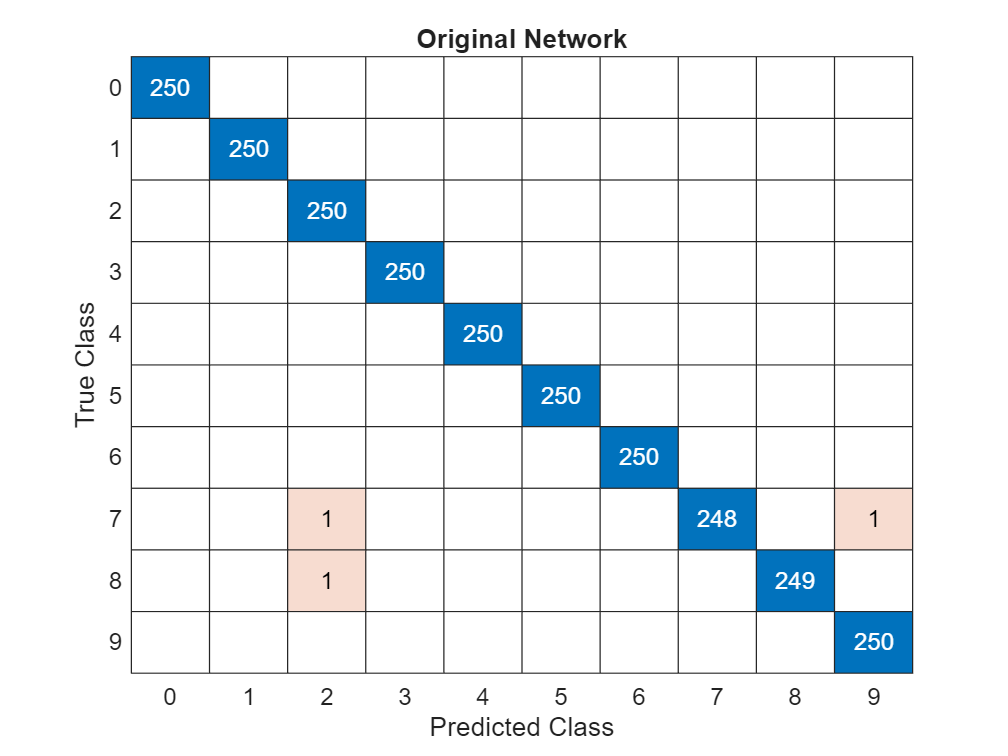

figure;
confusionchart(trueLabels, YPredOriginal);
title("Original Network");

The validation set of the digits data contains 250 images for each class, so if a network predicts the class of each image perfectly, all scores on the diagonal equal 250 and no values are outside of the diagonal.

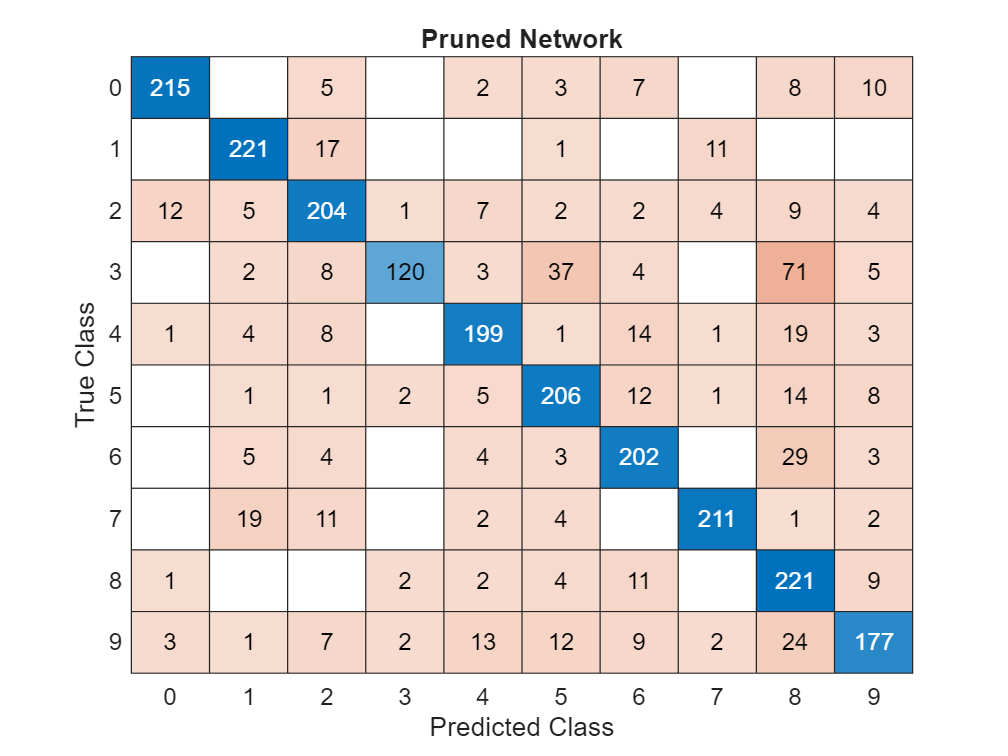

figure;
confusionchart(trueLabels, YPredPruned);
title("Pruned Network");

## 2.3 Quantize Pruned Network

Deep neural networks trained in MATLAB use single-precision floating point data types. Even networks that are small require a considerable amount of memory and hardware to perform floating-point arithmetic operations. These restrictions can inhibit deployment of deep learning models that have low computational power and less memory resources. By using a lower precision to store the weights and activations, you can reduce the memory requirements of the network. You can use Deep Learning Toolbox in tandem with the Deep Learning Model Quantization Library support package to reduce the memory footprint of a deep neural network by quantizing the weights, biases, and activations of the convolution layers to 8-bit scaled integer data types.

Pruning a network impacts the range statistics of parameters and activations at each layer, so the accuracy of the quantized network can change. To explore this difference, quantize the pruned network and use the quantized network to perform inference.

Split the data into calibration and validation data sets.

calibrationDataStore = splitEachLabel(imdsTrain,0.1,'randomize');
validationDataStore = imdsValidation;
% load the pruned model
load('digitsNet.mat','net')
load('digitsNet_0.90_iterativePruned_params_21578.mat','net')

Create a `dlquantizer` object and specify the pruned network as the network to quantize.

quantObjPrunedNetwork = dlquantizer(net,'ExecutionEnvironment','GPU');
quantOpts = dlquantizationOptions('Target','host'); %if you don't have a GPU then change 'gpu' to 'host'

Use the `calibrate` function to exercise the network with the calibration data and collect range statistics for the weights, biases, and activations at each layer.

calResults = calibrate(quantObjPrunedNetwork, calibrationDataStore)

Use the `validate` function to compare the results of the network before and after quantization using the validation data set.

valResults = validate(quantObjPrunedNetwork, validationDataStore, quantOpts);

calResults = 21×5 table
       Optimized Layer Name       Network Layer Name    Learnables / Activations    MinValue     MaxValue
    __________________________    __________________    ________________________    _________    ________

    "conv_1_Weights"                {'conv_1'    }           "Weights"               -0.67877     1.2341 
    "conv_1_Bias"                   {'conv_1'    }           "Bias"                   0.05982    0.05982 
    "conv_2_Weights"                {'conv_2'    }           "Weights"                -2.3837     3.1421 
    "conv_2_Bias"                   {'conv_2'    }           "Bias"                   -1.3916    0.94579 
    "conv_3_Weights"                {'conv_3'    }           "Weights"               -0.75624    0.84091 
    "conv_3_Bias"                   {'conv_3'    }           "B

Examine the `MetricResults.Result` field of the validation output to see the accuracy of the quantized network.

valResults.MetricResults.Result
valResults.Statistics %if you don't have a GPU then this won't display anything

ans = 2×2 table
    NetworkImplementation    MetricOutput
    _____________________    ____________

     {'Floating-Point'}         0.9904   
     {'Quantized'     }         0.9896   


Save the quantized network and calibration results

save('quantObjPrunedNetworkCalResults.mat','calResults');


ans =

     []



save('quantObjPrunedNetwork.mat','quantObjPrunedNetwork');

## References

[1] Song Han, Jeff Pool, John Tran, and William J. Dally. 2015. "Learning Both Weights and Connections for Efficient Neural Networks." Advances in Neural Information Processing Systems 28 (NIPS 2015): 1135–1143. 

[2] Hidenori Tanaka, Daniel Kunin, Daniel L. K. Yamins, and Surya Ganguli 2020. "Pruning Neural Networks Without Any Data by Iteratively Conserving Synaptic Flow."  *34th Conference on Neural Information Processing Systems (NeurlPS 2020)*

Copyright 2021 The MathWorks, Inc.